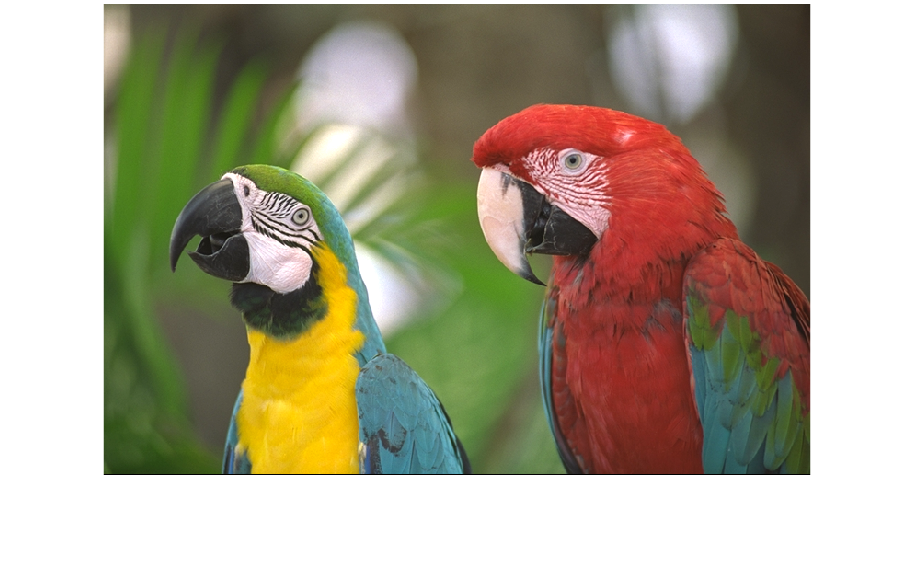

im1=double(imread('image1.png'))/255;

imshow(im1)


im1ycbcr = rgb2ycbcr(im1)

im1ycbcr = im1ycbcr(:,:,1) =

    0.4427    0.4460    0.4561    0.4508    0.4561    0.4561    0.4453    0.4651    0.4554    0.4554    0.4651    0.4587    0.4587    0.4562    0.4562    0.4596    0.4516    0.4461    0.4468    0.4468    0.4461    0.4360    0.4419    0.4273    0.4138    0.4090    0.4056    0.3829    0.3547    0.3404    0.3239    0.3277    0.3322    0.3277    0.3176    0.3239    0.3231    0.3239    0.3239    0.3176    0.3176    0.3142    0.3176    0.3075    0.3176    0.3210    0.3176    0.3184    0.3184    0.3086    0.3184    0.3130    0.3086    0.3183    0.3183    0.3086    0.3049    0.3130    0.3075    0.3142    0.3176    0.3130    0.3086    0.3086    0.3086    0.3086    0.3075    0.3075    0.3130    0.3075    0.3075    0.3041    0.3041    0.3086    0.3130    0.3049    0.3008    0.3075    0.3075    0.3075    0.3075    0.3041    0.3008    0.3075    0.3075    0.3075    0.3075    0.3041    0.3087    0.3087    0.3131    0.3087    0.3131    0.3075    0.3041    0.3075    0.3131

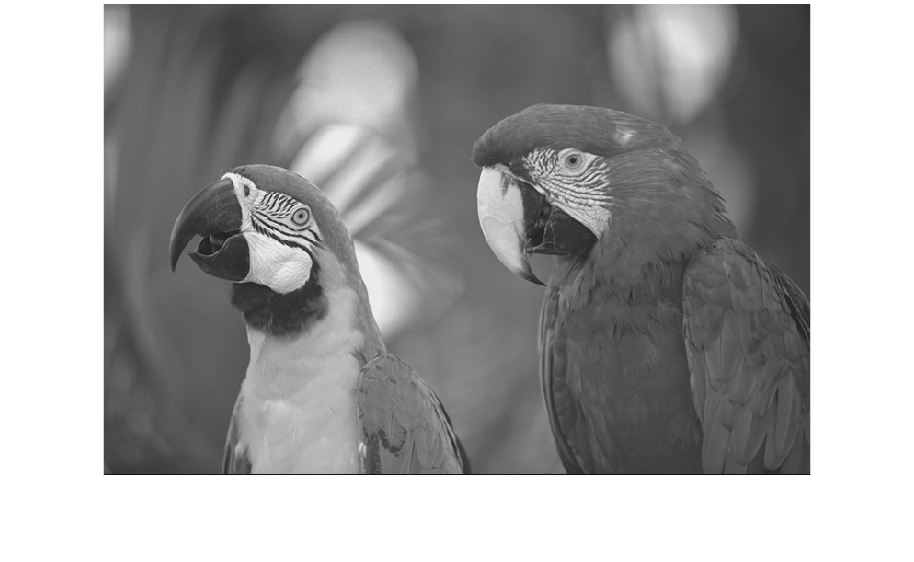

im1y = im1ycbcr(:,:,1);
im1cb = im1ycbcr(:,:,2);
im1cr = im1ycbcr(:,:,3);

imshow(im1y)



im1yd = bdct(im1y, [8 8])

im1yd =     3.9585    4.7586    5.2328    5.7908    6.1370    6.1254    6.0404    5.7797    5.3929    4.8626    4.3584    3.7875    3.3123    3.0134    2.7246    2.8322    2.9972    3.2566    3.6128    4.0045    4.1292    4.1174    4.0909    4.0056    3.8830    3.7377    3.5767    3.4524    3.2908    3.1442    2.9608    2.7770    2.6328    2.5089    2.3997    2.3159    2.2547    2.2269    2.2266    2.2768    2.3594    2.4104    2.5755    2.7332    2.8430    2.9267    2.9179    2.8287    2.7666    2.7505
   -0.2447   -0.1883   -0.1274   -0.1638   -0.0140    0.0070    0.0391    0.0946    0.1458    0.1451    0.1547    0.1651    0.1086    0.0881    0.0215   -0.0310   -0.0644   -0.0859   -0.1171   -0.1003    0.0107    0.0125    0.0162    0.0364    0.0385    0.0406    0.0377    0.0450    0.0457    0.0480    0.0504    0.0480    0.0379    0.0301    0.0380    0.0245    0.0124    0.0135   -0.0073   -0.0208   -0.0168   -0.0222   -0.0581   -0.0315   -0.0253   -0.0245    0.0355    0.0153    0.0199 




% imshow(ibdct(im1yr, [8 8], size(im1y)))

% Q1=0.1;
% im1ydq = bquant(im1yd, Q1);
% im1ydr = brec(im1ydq, Q1);
% im1yr = ibdct(im1ydr, [8 8], size(im1y));
% figure, imshow(im1yr - im1y);

QL=repmat(1:8, 8, 1); QL=(QL+QL'-9)/8

QL =    -0.8750   -0.7500   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0
   -0.7500   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250
   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500
   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750
   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750    0.5000
   -0.2500   -0.1250         0    0.1250    0.2500    0.3750    0.5000    0.6250
   -0.1250         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500
         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750


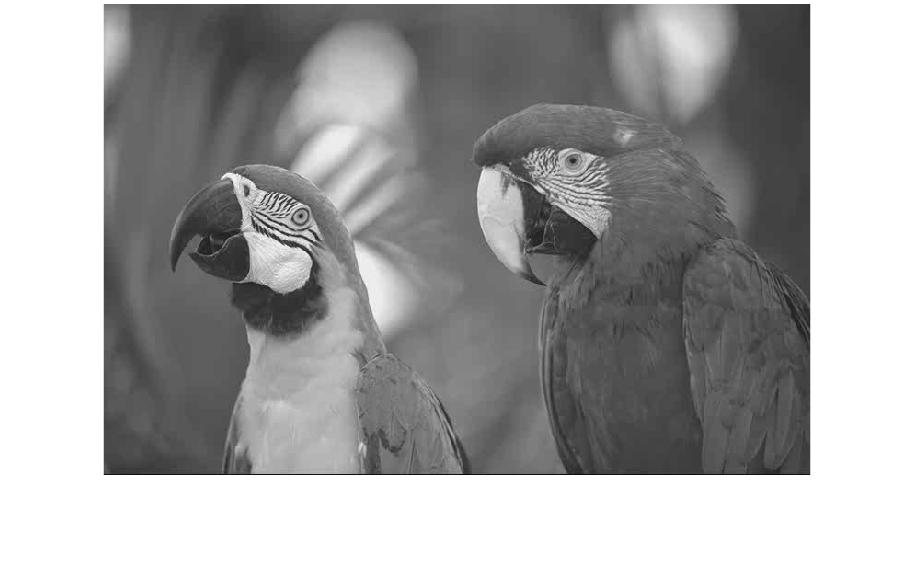

k1=0.1; k2=0.3;
Q2=k1*(1+k2*QL);
im1ydq = bquant(im1yd, Q2);
im1ydr = brec(im1ydq, Q2);
im1yr = ibdct(im1ydr, [8 8], size(im1y));
figure, imshow(im1yr);


dist = mean((im1y(:)-im1yr(:)).^2)

dist = 1.3117e-04

psnr = 10*log10(1/dist)

psnr = 38.8217



% Source coding

p = ihist(im1ydq(:))

p =            1           0           1           0           1           2           2           4           2           8           7           9          11           8          34          35          51          72         105         180         313         589        1403        6576      367737        6928        1439         677         328         211          97          81          40          40          21          20          11           7           4           4           4           3           5           3           3          13          28          41          31          59



% Static huffman
% bits = huffman(p)
% bpp = bits/(length(im1y(:,1)) * length(im1y(1,:)))
pixels = length(im1y(:,1)) * length(im1y(1,:))

pixels = 393216

% Dynamic huffman
bits=0;
for k=1: size (im1ydq, 1)
    p = ihist(im1ydq(k,:));
    bits = bits + huffman(p);
end
bpp = bits/pixels

bpp = 1.1845


bits = sum(jpgrate(im1ydq, [8 8]));
bpp = bits/pixels

bpp = 0.3468

Code

clear
% [psnr, bpp] = transcoder('image1.png', [40 40], 0.1, 0.1)

% psnr
% bpp

numberOfBlockSizes = 3;
blockSizeStart = 8;

numberOfStepSizes = 80

numberOfStepSizes = 80

stepSizeScale = 0.3

stepSizeScale = 0.3000

stepSizeStart = 0.1

stepSizeStart = 0.1000


res = zeros(2, numberOfStepSizes, numberOfBlockSizes);

stepsize_lower = 0.01

stepsize_lower = 0.0100

stepsize_upper = 0.5

stepsize_upper = 0.5000

numberOfStepSizes = 15

numberOfStepSizes = 15

stepsizes = logspace(log10(stepsize_lower),log10(stepsize_upper),numberOfStepSizes);

for blockSize = 1:numberOfBlockSizes
    blockSize + blockSizeStart
    for stepSize = 1:numberOfStepSizes
        [psnr, bpp] = transcoder( ...
            'image1.png', ...
            [blockSize+blockSizeStart blockSize+blockSizeStart], ...
            stepsizes(stepSize), ...
            stepsizes(stepSize)*1.2, ...
            0.5, ...
            true ...
        );

            %             stepSize*stepSizeScale + stepSizeStart, ...
%             stepSize*stepSizeScale + stepSizeStart, ...

        res(:, stepSize, blockSize) = [psnr, bpp];
    end
end

ans = 9

ans = 10

ans = 11

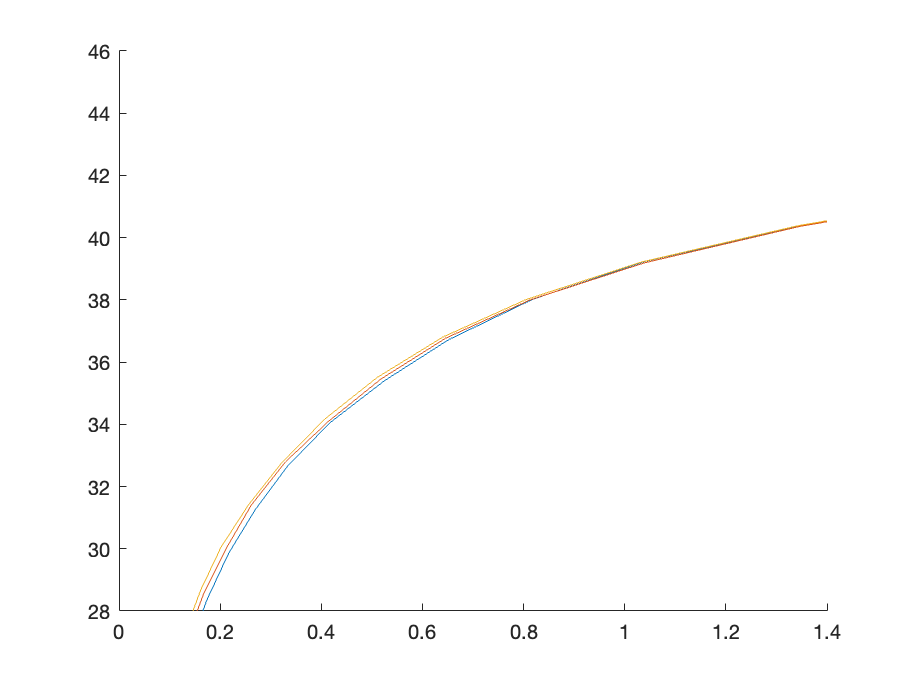

figure
xlim([0, 1.4])
ylim([28, 46])

% xlim([0, 5])
% ylim([0, 40])

hold on
for i = 1:numberOfBlockSizes
    plot(res(2,:,i), res(1,:,i))
end
hold off